# TAREA 4

## IE0431 Sistemas de Control - Universidad de Costa Rica, Escuela de Ingeniería Eléctrica

## Diego Alfaro Segura, C20259, grupo 01

clc
clear
close all

s = tf('s');

% Funciones de transferencia según carnet
carnet = [5 2 5 9]; % Se reemplaza el 0 por un 5

## 1) Subamortiguado con un cero

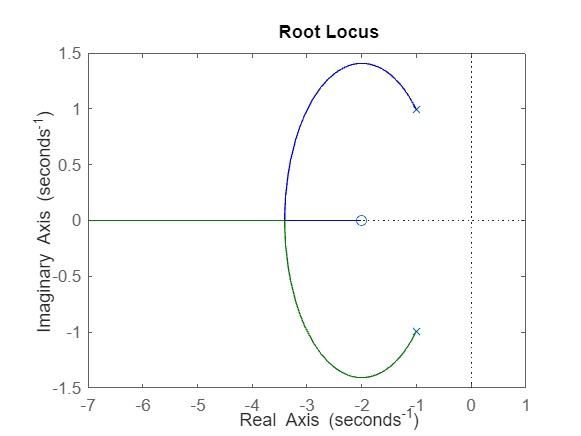

% Función personalizada
alpha = 0.11*max(carnet);
beta = 0.15*min(carnet) + 1.5;
Psubc = (beta*(s+2))/(s^2+2*s+1+alpha^2);

% LGR del proceso
rlocus(Psubc)

#### 1.1

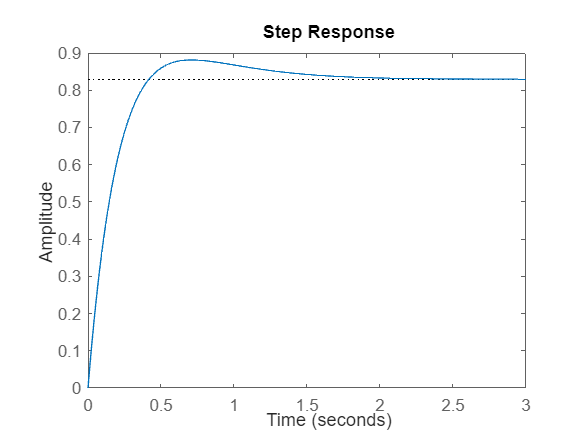

%% Encontrar punto de entrada en eje real con regla 8 y conseguir K
syms k(o) x;

% Ecuación de punto de cruce encontrada
k(o) = -(o^2 +2*o + (1+alpha^2))/(beta*(o+2));

% Derivar y encontrar o de cruce 
Dko = diff(k, o);
o_array = solve(Dko == 0, o);
o_cruce = -1*double(o_array(1)); % Se toma el primer o encontrado, pues es el correcto

% Controlador y respuesta
C_1_1 = 2*(o_cruce-1)/beta;
Myr_1_1 = feedback(C_1_1*Psubc, 1);
step(Myr_1_1)


% Cálculo de ta2%, Mpn y epr0
wn_1_1 = o_cruce;
zeta_1_1 = 1;
ta2_1_1 = 4/(wn_1_1*zeta_1_1)

ta2_1_1 = 1.1740

Mpn_1_1 = 100*exp(-(zeta_1_1*pi)/sqrt(1-zeta_1_1^2))

Mpn_1_1 = 0

epr0_1_1 = limit((x^2 + 2*x + (1+alpha^2))/(x+o_cruce)^2, x, 0)

$$epr0\_1\_1 = 0.1706$$

#### 1.2

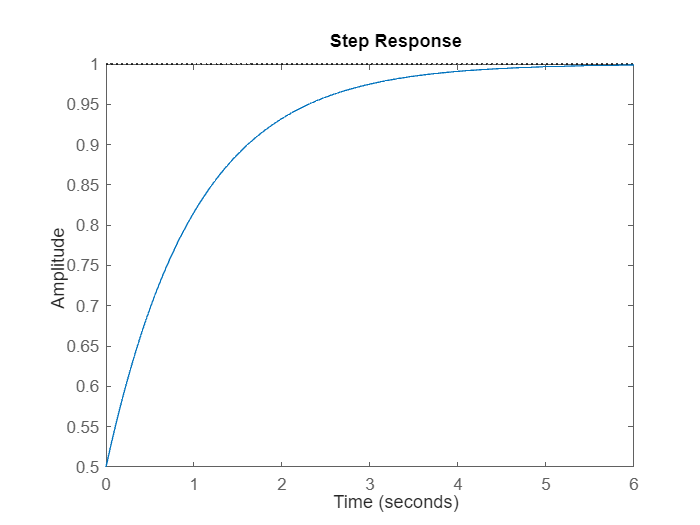

% Parámetros calculados
Td_1_2 = 0.5;
Ti_1_2 = 1/((1+alpha^2)*Td_1_2);
K_1_2 = 1/(Td_1_2*beta);

% Controlador y respuesta
C_1_2 = K_1_2*(1 + 1/(Ti_1_2*s) + Td_1_2*s);
Myr_1_2 = feedback(C_1_2*Psubc, 1);
step(Myr_1_2)


% Cálculo de ta2%, Mpn y epr0
ta2_1_2 = 4

ta2_1_2 = 4

Mpn_1_2 = 0

Mpn_1_2 = 0

epr0_1_2 = limit(x/(x+1)^2, x, 0)

$$epr0\_1\_2 = 0$$

## 2) Proceso inestable

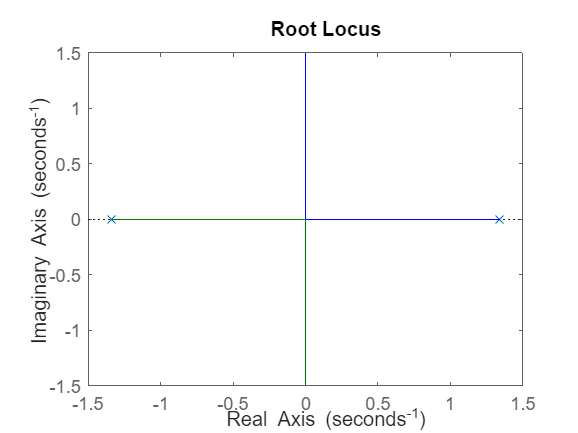

% Proceso inestable
alpha_ins = 0.2*max(carnet);
beta_ins = 0.2*min(carnet) + 1.5;
Pins = beta_ins/(s^2 - alpha_ins);

% LGR del proceso
rlocus(Pins)

#### 2.1

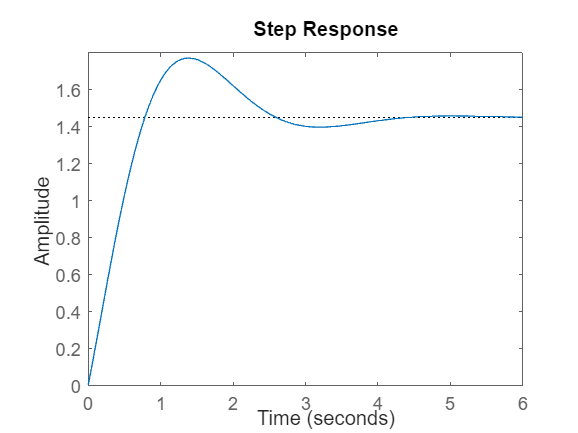

% Parámetros calculados
K_2_1 = (4+alpha_ins)/beta_ins;
Td_2_1 = 2/(K_2_1*beta_ins);

% Controlador y respuesta
C_2_1 = K_2_1*(Td_2_1*s+1);
Myr_2_1 = feedback(C_2_1*Pins, 1);
step(Myr_2_1)

#### 2.2

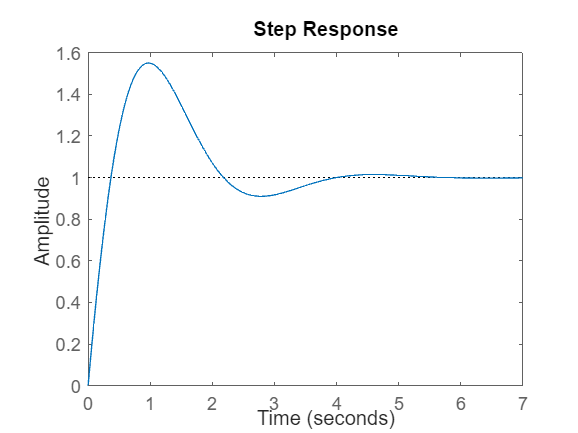

% Parámetros calculados
K_2_2 = 4/beta_ins;
Ti_2_2 = 1/sqrt(alpha_ins);
Td_2_2 = (2 + sqrt(alpha_ins))/(K_2_2*beta_ins);

% Controlador y respuesta
C_2_2 = K_2_2*(Td_2_2*s + 1)*(s + 1/Ti_2_2)/s;
Myr_2_2 = feedback(C_2_2*Pins, 1);
step(Myr_2_2)

## 3. Comprobación de diseños con sisotool

#### Comprobación 1.1

cargar_1_1 = questdlg('¿Cargar la sesión del punto 1.1?', ...
    'Cargar sesión', ...
    'Yes', 'No', 'No');
if strcmp(cargar_1_1, 'Yes')
    sisotool('1_1.mat')
end

#### Comprobación 1.2

cargar_1_2 = questdlg('¿Cargar la sesión del punto 1.2?', ...
    'Cargar sesión', ...
    'Yes', 'No', 'No');
if strcmp(cargar_1_2, 'Yes')
    sisotool('1_2.mat')
end

#### Comprobación 2.1

cargar_2_1 = questdlg('¿Cargar la sesión del punto 2.1?', ...
    'Cargar sesión', ...
    'Yes', 'No', 'No');
if strcmp(cargar_2_1, 'Yes')
    sisotool('2_1.mat')
end

#### Comprobación 2.2

cargar_2_2 = questdlg('¿Cargar la sesión del punto 2.2?', ...
    'Cargar sesión', ...
    'Yes', 'No', 'No');
if strcmp(cargar_2_2, 'Yes')
    sisotool('2_2.mat')
end

## 4. Diseños discretos

% Tiempo de muestreo
Ts = 0.005;

z = tf('z',Ts);

#### 1.2

ERPsubc = c2d(Psubc,Ts,'ZOH');
zpk(ERPsubc)

ans =
 
   0.0089999 (z-0.99)
  --------------------
  (z^2 - 1.99z + 0.99)
 
Sample time: 0.005 seconds
Discrete-time zero/pole/gain model.
Model Properties


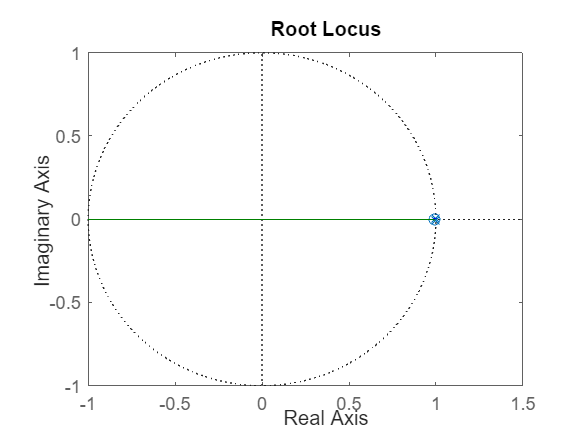

rlocus(ERPsubc)


% Controlador obtenido con sisotool
K_4_1 = 0.64331;
a_4_1 = -0.993;

Kp_4_1 = -K_4_1*a_4_1

Kp_4_1 = 0.6388

Ki_4_1 = K_4_1 - Kp_4_1

Ki_4_1 = 0.0045

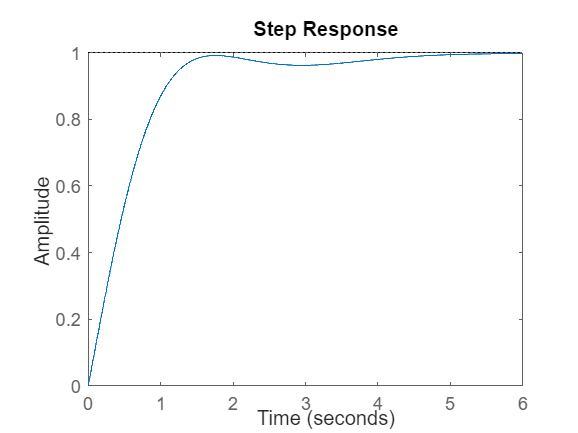


% Controlador y respuesta
C_4_1 = ((Kp_4_1 + Ki_4_1)*z - Kp_4_1)/(z-1);
Myr_4_1 = feedback(C_4_1*ERPsubc, 1);
step(Myr_4_1)



cargar_4_1 = questdlg('¿Cargar la sesión del punto 4.1?', ...
    'Cargar sesión', ...
    'Yes', 'No', 'No');
if strcmp(cargar_4_1, 'Yes')
    sisotool('4_1.mat')
end

#### 2.1

ERPins = c2d(Pins,Ts,'ZOH');
zpk(ERPins)

ans =
 
    2.375e-05 (z+1)
  --------------------
  (z-1.007) (z-0.9933)
 
Sample time: 0.005 seconds
Discrete-time zero/pole/gain model.
Model Properties


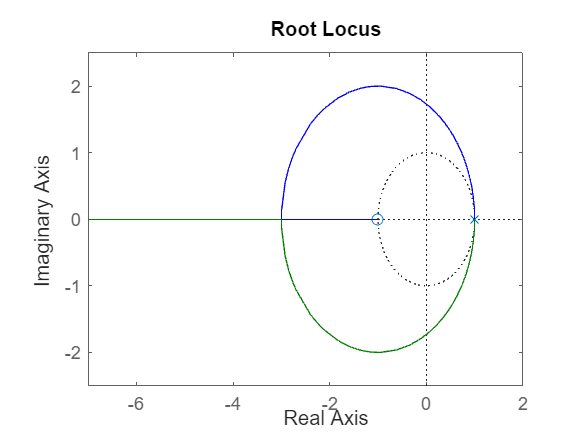

rlocus(ERPins)


% Controlador obtenido con sisotool
K_4_2 = 0.1968/2.375e-05;
a_4_2 = -1.931;
b_4_2 = 0.9314;

Kd_4_2 = K_4_2*b_4_2

Kd_4_2 = 7.7179e+03

Kp_4_2 = -K_4_2 -2*Kd_4_2

Kp_4_2 = -2.3722e+04

Ki_4_2 = K_4_2 - Kp_4_2 -Kd_4_2

Ki_4_2 = 2.4291e+04

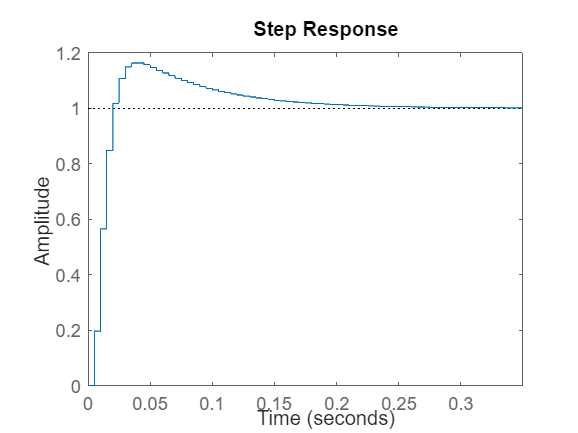


% Controlador y respuesta
C_4_2 = K_4_2*(z^2+a_4_2*z+b_4_2)/(z*(z-1));
Myr_4_2 = feedback(C_4_2*ERPins, 1);
step(Myr_4_2)


cargar_4_2 = questdlg('¿Cargar la sesión del punto 4.2?', ...
    'Cargar sesión', ...
    'Yes', 'No', 'No');
if strcmp(cargar_4_1, 'Yes')
    sisotool('4_2.mat')
end